## TEST

Wymiar rzeczywisty jednego tagu w metrach

tagSize = 0.184;

Kalibracja kamery

test = imread("test3.jpeg");
focalLength    = [4*3024/4.2 4*4032/5.6]; %długość ogniskowej razy ImageSize - automatyczne szczytywanie(?)
principalPoint = [2016 1512]; %do ustalenia
imageSize      = [3024 4032];
intrinsics = cameraIntrinsics(focalLength , principalPoint , imageSize);
test = undistortImage(test,intrinsics,OutputView="same");

Określenie pozycji tagów

[id , loc , pose] = readAprilTag(test , "tag36h11" , intrinsics , tagSize);

Ustawienie centrum wektorów

worldPoints = [0 0 0; tagSize/2 0 0; 0 tagSize/2 0; 0 0 tagSize/2];
for i = 1 : length(pose)
    % Get image coordinates for axes.
    imagePoints = world2img(worldPoints , pose(i) , intrinsics);
    % Draw colored axes.
    test = insertShape(test , Line=[imagePoints(1,:) imagePoints(2,:); ...
        imagePoints(1,:) imagePoints(3,:); imagePoints(1,:) imagePoints(4,:)], ...
        Color=["red","green","blue"],LineWidth=7);
    test = insertText(test,loc(1,:,i),id(i),BoxOpacity=1,FontSize=25);
end
pose.Translation

ans =    -0.1772   -1.1100    2.6293


ans =     0.4172    0.2570    2.7633


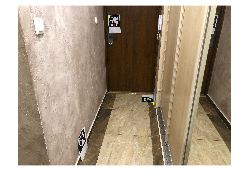

imshow(test)

## GUI

- Wyświetlanie zdjęcia

- Wyświetlanie pozycji tagu

- Wpisanie rozmiaru tagu i domniemana pozycja drona względem taga

- Wyświetlanie błędu (będzie zastąpione wykresem)

%App_test01;                     %Uruchomienie GUI

## MAIN

 Wymiar rzeczywisty jednego tagu w metrach

tagSize = 0.184;

Wywołanie funkcji (main):

- Pokazanie kilku scenariuszy(zdjęcia)

- do 3 m jest nieduży błąd

translated = calculate_poses("test1.jpeg", [3024 4032], tagSize, 4, [4.2 5.6]) % przesunięcie
error = calculate_diff(translated , 2.821) %błąd
translated = calculate_poses("test2.jpeg", [3024 4032], tagSize, 4, [4.2 5.6])
error = calculate_diff(translated , [2.822 2.940])
translated = calculate_poses("test3.jpeg", [3024 4032], tagSize, 4, [4.2 5.6])
error = calculate_diff(translated , [3.258 3.276])

%!!!!!!!!!!! Cała ta sekcja wymaga zainstalowania biblioteki Ryze Tello
%Drone i wcześniejszej konfiguracji połączenia

%warunki początkowe
actionDistance=0.5; %w metrach
actionDistanceAccuracy=0.01; %w metrach
actionRotationAccuracy=0.02; %w radianach

%połączenie z dronem oraz start
droneObj = ryze()
cameraObj = camera(droneObj)
frame = snapshot(cameraObj)
%takeoff(droneObj);

%główna pętla sterująca
%while true
%
%    frame = snapshot(cameraObj);
%    rotation = calculate_rotation(frame);
%    translated = calculate_poses(frame, [720 960], tagSize, 4, [4.2 5.6]);
%
%    if (rotation<actionRotationAccuracy && rotation>actionRotationAccuracy) && (translated(1)<actionDistanceAccuracy && translated(1)>(-actionDistanceAccuracy) && translated(2)<actionDistanceAccuracy && translated(2)>(-actionDistanceAccuracy) && (translated(3)-actionDistance)<actionDistanceAccuracy && (translated(3)-actionDistance)>(-actionDistanceAccuracy))
%        flip(droneObj,'back');
%    else
%        move(droneObj,[translated(1) translated(2) translated(3-actionDistance)],'WaitUntilDone',true);
%        turn(droneObj,deg2rad(rotation));
%    end
%
%    pause(1);
%
%end


## Image Processing

Funkcja licząca przesunięcie względem kamery:

- parametry(focalLength , principalPoint , imageSize , nazwa pliku/kamery)

- powinna zwracać pozycję tagu w px(?) pose.A , pose.R 

- Czy da się zwracać parametry zdjęcia automatycznie?

function [translated_pose] = calculate_poses(image_dir, image_size, tag_size, focal_length, sensor_size)

image = imread(image_dir);
focal_length_xy = [focal_length*image_size(1)/sensor_size(1) focal_length*image_size(2)/sensor_size(2)];
principal_point = [image_size(2)/2 image_size(1)/2];
intrinsics = cameraIntrinsics(focal_length_xy , principal_point , image_size);

image = undistortImage(image,intrinsics,OutputView="same");

[~ , ~ , pose] = readAprilTag(image , "tag36h11" , intrinsics , tag_size);

translated_pose = [pose.Translation];

end

Funkcja licząca kąt położenia względem kamery (w radianach):

function [rotation] = calculate_rotation(image_dir)
tagFamily = ["tag36h11","tagCircle21h7","tagCircle49h12","tagCustom48h12","tagStandard41h12"];
image = imread(image_dir);

[id,loc] = readAprilTag(image,tagFamily);
x=zeros(length(id));

for idx = 1:length(id)

    y1=abs(loc(1,2,idx)-loc(4,2,idx));
    y2=abs(loc(2,2,idx)-loc(3,2,idx));

    if y1<=y2
        div=y1/y2;
        sign=1;
    else
        div=y2/y1;
        sign=-1;
    end

    
    alfa=acos(div)*sign;
    x(idx)=alfa;
end

rotation=x;

end

Funkcja przeliczenia błędu w metrach i procentach

function [diffrence] = calculate_diff(translated, straigth)

for i = 1 : size(translated)
    x = translated(i);
    y = translated(i + 1);
    z = translated(i + 2);
    calc = (z^2 + x^2 + y^2)^0.5 - straigth; %błąd w metrach
    percent = abs((calc / 2.821)) * 100; %błąd w procentach
    [diffrence] = [calc ; percent];
end
end

## UAV

Funkcje sterujące drona TeloEDU

- takeoff() - start

- land() - lądowanie

- abord() - porzucenie akcji (zabezpieczenie

- flip() - akcja specjalnapo

- move()  - ruch w trzech osiach, można ustawić prędkość

- [https://ch.mathworks.com/help/supportpkg/ryzeio/?fbclid=IwAR0d1CZ-L-gUaGQvR-8JU5ylpVCfbrL1vHODADbfwQ_QH6Mx0SD6wD3GNEY](https://ch.mathworks.com/help/supportpkg/ryzeio/?fbclid=IwAR0d1CZ-L-gUaGQvR-8JU5ylpVCfbrL1vHODADbfwQ_QH6Mx0SD6wD3GNEY)

- pozostałą dokumentacja ''

w pętli while 

- Pobranie snapshota

- Przliczenie pozycji oraz obrotu tagu

- Obliczenie wektorów przesunięcia

- Przesłanie wektorów do funkcji sterującej dronem

Później